clc

GlassStrain = flip(Glass1Indentation.VarName1)

GlassStrain =     0.2455
    0.2524
    0.2773
    0.2905
    0.3078
    0.3264
    0.3431
    0.3770
    0.3901
    0.4164


GlassXdiff = flip(Glass1Indentation.VarName3)

GlassXdiff =     0.0421
    0.0363
    0.0415
    0.0396
    0.0418
    0.0402
    0.0334
    0.0376
    0.0376
    0.0415


GlassYdiff = flip(Glass1Indentation.VarName5)

GlassYdiff =     0.0414
    0.0297
    0.0462
    0.0365
    0.0452
    0.0378
    0.0262
    0.0388
    0.0310
    0.0430


GlassSum = flip(Glass1Indentation.VarName7)

GlassSum =     1.8524
    1.8553
    1.8518
    1.8550
    1.8521
    1.8537
    1.8556
    1.8527
    1.8550
    1.8524


SpringConst = 0.32;

Glass_smooth_Strain = smoothdata(GlassStrain)

Glass_smooth_Strain =     1.9288
    1.9415
    1.9542
    1.9670
    1.9797
    1.9924
    2.0052
    2.0180
    2.0308
    2.0436


Glass_smooth_Ydiff = smoothdata(GlassYdiff)

Glass_smooth_Ydiff =     0.0408
    0.0409
    0.0406
    0.0408
    0.0410
    0.0409
    0.0412
    0.0413
    0.0415
    0.0419



% Plot the data
figure
hold on
plot(Glass_smooth_Strain, Glass_smooth_Ydiff, '-', 'Color', '#890aff')
xlabel('Strain Displacement (um)')
ylabel('YDiff Voltage (V)')

% Manual Selection of Starting and Ending Points to Curve Fit
title('Start Point Selection')
[GlassstartX, ~] = ginput(1)

GlassstartX = 17.0253

title('End Point Selection')
[GlassendX, ~] = ginput(1)

GlassendX = 17.5645


% Find indices corresponding to the selected points
startGlass = find(Glass_smooth_Strain >= GlassstartX, 1, 'first')

startGlass = 617

endGlass = find(Glass_smooth_Strain <= GlassendX, 1, 'last')

endGlass = 648


% Curve fit
degree = 1

degree = 1

coeffGlass = polyfit(Glass_smooth_Strain(startGlass:endGlass), Glass_smooth_Ydiff(startGlass:endGlass), degree)

coeffGlass =     1.6306  -27.2568



% Plot the fitted curve onto the original graph
plot(Glass_smooth_Strain, endGlass, '-', 'Color', '#890aff')
plot(Glass_smooth_Strain(startGlass:endGlass), Glass_smooth_Ydiff(startGlass:endGlass), 'o', 'MarkerSize', 10, 'Color', 'r')
Glassfittedcurve = polyval(coeffGlass, Glass_smooth_Strain(startGlass:endGlass))

Glassfittedcurve =     0.5288
    0.5558
    0.5828
    0.6099
    0.6369
    0.6639
    0.6910
    0.7180
    0.7450
    0.7721


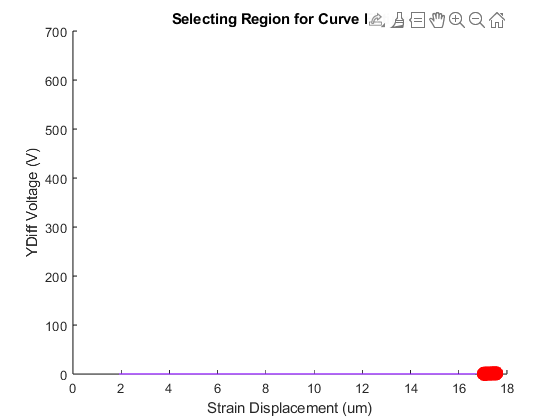

plot(Glass_smooth_Strain(startGlass:endGlass), Glassfittedcurve, 'r', 'LineWidth', 2)
hold off

title('Selecting Region for Curve Fitting')
xlabel('Strain Displacement (um)')
ylabel('YDiff Voltage (V)')

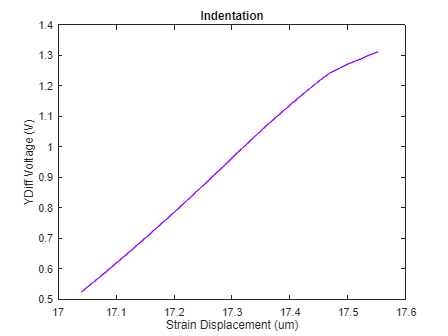


%Identify Point of Contact
figure
plot(Glass_smooth_Strain(startGlass:endGlass), Glass_smooth_Ydiff(startGlass:endGlass), '-', 'Color', '#890aff')
title('Indentation')
xlabel('Strain Displacement (um)')
ylabel('YDiff Voltage (V)')


slope = coeffGlass(1)

slope = 1.6306